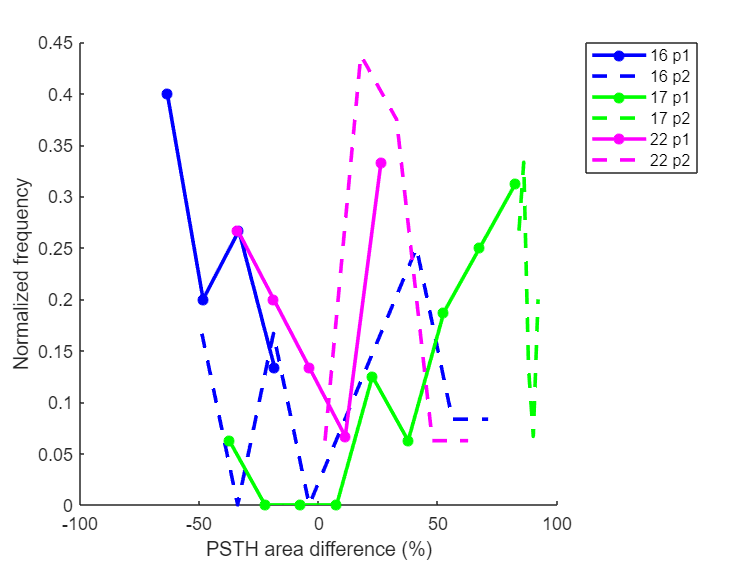

clear all
clc

a=[struct2array(load("dif_s2_p1.mat")); struct2array(load("dif_s2_p2.mat")); 
    struct2array(load("dif_s3_p1.mat")); struct2array(load("dif_s3_p2.mat"));
    struct2array(load("dif_s5_p1.mat")); struct2array(load("dif_s5_p2.mat"))];

figure

a1=a(1,:);
n=15;
bin_size=n;
n_bin=round((max(a1)-min(a1))/n);
ppp=min(a1);
va1=zeros(n_bin,1);
for j=1:n_bin
va1(j,1)=length(a1(a1 >= ppp & a1 < ppp+bin_size));
ppp=ppp+bin_size;
end
va1=va1/sum(va1);
o1=min(a1):n:min(a1)+n*(n_bin-1);
plot(o1,va1,'-*b','LineWidth',2)
hold on
box 

a2=[a(2,1) a(2,3:end)];
n=15;
bin_size=n;
n_bin=round((max(a2)-min(a2))/n);
ppp=min(a2);
va2=zeros(n_bin,1);
for j=1:n_bin
va2(j)=length(a2(a2 >= ppp & a2 < ppp+bin_size));
ppp=ppp+bin_size;
end
va2=va2/sum(va2);
o2=min(a2):n:min(a2)+n*(n_bin-1);
plot(o2,va2,'LineStyle','--','LineWidth',2,'Color','b')
hold on
box off

a3=a(3,:);
n=15;
bin_size=n;
n_bin=round((max(a3)-min(a3))/n);
ppp=min(a3);
va3=zeros(n_bin,1);
for j=1:n_bin
va3(j)=length(a3(a3 >= ppp & a3 < ppp+bin_size));
ppp=ppp+bin_size;
end
va3=va3/sum(va3);
o3=min(a3):n:min(a3)+n*(n_bin-1);
plot(o3,va3,'-*g','LineWidth',2)
hold on
box off

a4=a(4,2:end);
n=2;
bin_size=n;
n_bin=round((max(a4)-min(a4))/n);
ppp=min(a4);
va4=zeros(n_bin,1);
for j=1:n_bin
va4(j)=length(a4(a4 >= ppp & a4 < ppp+bin_size));
ppp=ppp+bin_size;
end
va4=va4/sum(va4);
o4=min(a4):n:min(a4)+n*(n_bin-1);
plot(o4,va4,'LineStyle','--','LineWidth',2,'Color','g')
hold on
box off

a5=a(5,:);
n=15;
bin_size=n;
n_bin=round((max(a5)-min(a5))/n);
ppp=min(a5);
va5=zeros(n_bin,1);
for j=1:n_bin
va5(j)=length(a5(a5 >= ppp & a5 < ppp+bin_size));
ppp=ppp+bin_size;
end
va5=va5/sum(va5);
o5=min(a5):n:min(a5)+n*(n_bin-1);
plot(o5,va5,'-*m','LineWidth',2)
hold on
box off

a6=a(6,:);
n=15;
bin_size=n;
n_bin=round((max(a6)-min(a6))/n);
ppp=min(a6);
va6=zeros(n_bin,1);
for j=1:n_bin
va6(j)=length(a6(a6 >= ppp & a6 < ppp+bin_size));
ppp=ppp+bin_size;
end
va6=va6/sum(va6);
o6=min(a6):n:min(a6)+n*(n_bin-1);
plot(o6,va6,'LineStyle','--','LineWidth',2,'Color','m')
hold on
box off

%ylim([0 0.3])
%xlim([0 100])
ylabel('Normalized frequency')
xlabel('PSTH area difference (%)')
legend('16 p1','16 p2','17 p1','17 p2','22 p1','22 p2','Location', 'bestoutside')